%Очистка предыдущих переменных, графиков, файлов
close all;
clear valuables;


%Подключение данных
data = importdata("data.txt");
scale = importdata("settings.txt");


%Обработка данных
dV = scale(1);
U = data * dV;
dt = scale(2); 
t = ((1:length(data)) * dt)';

[M, I] = max(data,[],'linear')

M = 247

I = 384

tCharge = t(I);
tDischarge = max(t) - tCharge;


%Визуализация данных
f1 = figure()

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


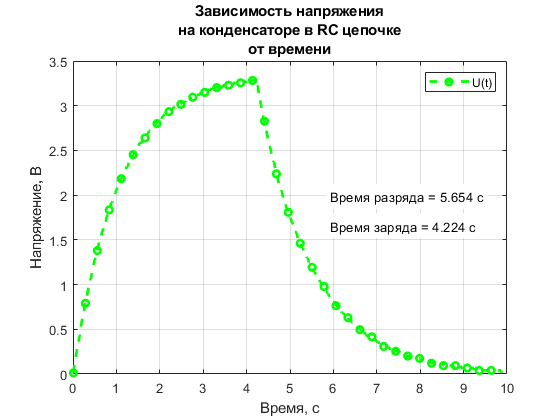

plot(t, U, '--o', 'Color', [0, 1, 0],'MarkerIndices',1:25:length(t), 'LineWidth',2, 'MarkerSize',5 );
grid on;
title({'Зависимость напряжения' 'на конденсаторе в RC цепочке' 'от времени'})
xlabel("Время, с");
ylabel("Напряжение, В");
legend("U(t)", 'Location','northeast');
text(max(t)*0.6, max(U)*0.5, ['Время заряда = ', num2str(tCharge), ' c'], 'BackgroundColor', [1,1,1]);
text(max(t)*0.6, max(U)*0.6, ['Время разряда = ', num2str(tDischarge), ' c'], 'BackgroundColor', [1,1,1]);
set(gcf, 'Visible', 'on');

%Сохранение графика в файл
saveas(f1, "capacitor.png")
saveas(f1, "capacitor.svg")